# Kalman Consensus Filter

## Setup

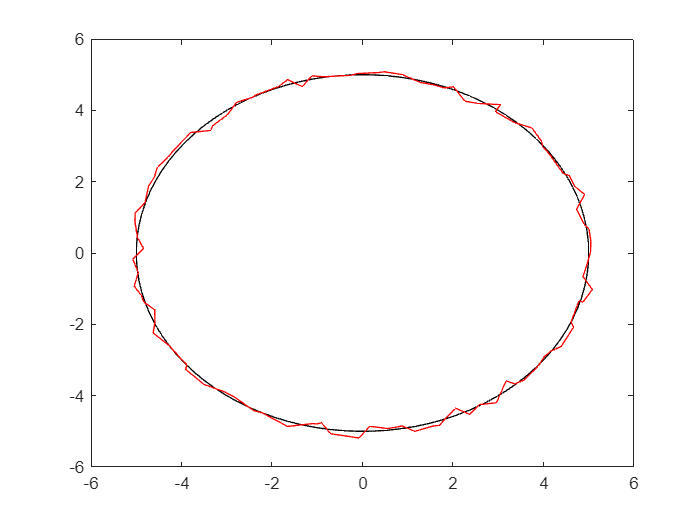

del_t = 1;
random_acc_sd = 0.2;
sensor_noise = [0,0,0,0;0.1,0.4,0.8,1.2];
N = 4;
eps = 0.3;

init_x = [0 0 0 0 0 0]';
f = [1 del_t 0.5*power(del_t,2) 0 0 0;
     0 1 del_t 0 0 0;
     0 0 1 0 0 0;
     0 0 0 1 del_t 0.5*power(del_t,2);
     0 0 0 0 1 del_t;
     0 0 0 0 0 1];

init_p = [500 0 0 0 0 0;
          0 500 0 0 0 0;
          0 0 500 0 0 0;
          0 0 0 500 0 0;
          0 0 0 0 500 0;
          0 0 0 0 0 500];

q = [power(del_t,4)/4 power(del_t,3)/2 power(del_t,2)/2 0 0 0;
     power(del_t,3)/2 power(del_t,2)/2 del_t 0 0 0;
     power(del_t,2)/2 del_t 1 0 0 0;
     0 0 0 power(del_t,4)/4 power(del_t,3)/2 power(del_t,2)/2;
     0 0 0 power(del_t,3)/2 power(del_t,2)/2 del_t;
     0 0 0 power(del_t,2)/2 del_t 1];
q = q * power(random_acc_sd,2);

h = [1 0 0 0 0 0;
     0 0 0 1 0 0];

r1 = [power(sensor_noise(2,1),2) 0;
      0 power(sensor_noise(2,1),2)];
r2 = [power(sensor_noise(2,2),2) 0;
      0 power(sensor_noise(2,2),2)];
r3 = [power(sensor_noise(2,3),2) 0;
      0 power(sensor_noise(2,3),2)];
r4 = [power(sensor_noise(2,4),2) 0;
      0 power(sensor_noise(2,4),2)];


figure;
[true_x,true_y] = gen_true_val(0,0,5);
draw_trajectory(true_x,true_y,'k');
hold on;
z1 = gen_sens_val(0,0,5,sensor_noise(1,1),sensor_noise(2,1));
z2 = gen_sens_val(0,0,5,sensor_noise(1,2),sensor_noise(2,2));
z3 = gen_sens_val(0,0,5,sensor_noise(1,3),sensor_noise(2,3));
z4 = gen_sens_val(0,0,5,sensor_noise(1,4),sensor_noise(2,4));

itr = 100;
z = zeros(2,length(z1),4);
z(:,:,1) = z1;
z(:,:,2) = z2;
z(:,:,3) = z3;
z(:,:,4) = z4;

draw_trajectory(z1(1,:),z1(2,:),'r');

% draw_trajectory(z2(1,:),z2(2,:),'g');
% draw_trajectory(z3(1,:),z3(2,:),'b');
% draw_trajectory(z4(1,:),z4(2,:),'m');


## Initialization

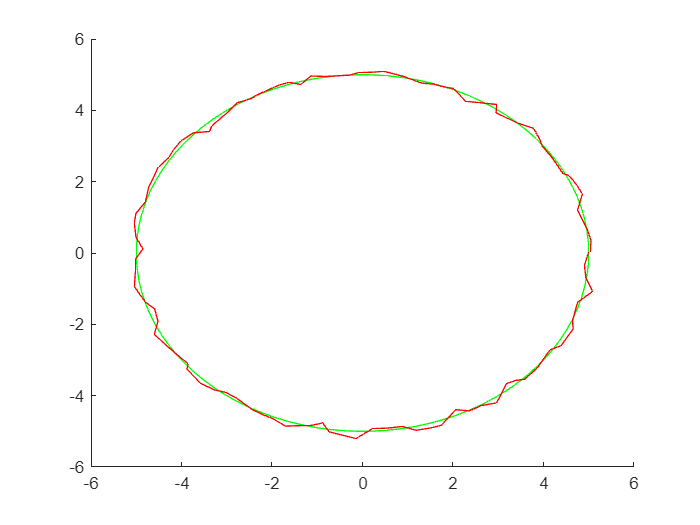

% Prediction Step
x_1 = f*init_x;
p_1 = f*init_p*f' + q;

x_2 = x_1;
p_2 = p_1;

x_3 = x_1;
p_3 = p_1;

x_4 = x_1;
p_4 = p_1;

X_0 = [x_1 x_2 x_3 x_4];
P_0 = zeros(6,6,N);
P_0(:,:,1) = p_1;
P_0(:,:,2) = p_2;
P_0(:,:,3) = p_3;
P_0(:,:,4) = p_4;

JR = ["r1","r2","r4";
      "r2","r3","r1";
      "r3","r4","r2";
       "r4","r1","r3"];

JZ = ["z1","z2","z4";
      "z2","z3","z1";
      "z3","z4","z2";
      "z4","z1","z3"];

% J = [4 1 2; 1 2 3; 2 3 4; 3 4 1];

X_est = NaN(6,length(z1));
P_est = NaN(6,6,length(z1));

X_pred = NaN(6,1,length(z1));
P_pred = NaN(6,6,length(z1));

for i = 1:length(z1)
    if i == 1
        % At each iterations
        for n = 1:4
            % for every sensor
            msg.y_i = zeros(6,N-1);
            msg.s_i = zeros(6,6,N-1);
            msg.x_i = zeros(2,N-1);
            for nei = 1:3
                % for every neighbour
                r_nei = eval(JR(n,nei));
                z_nei = eval(JZ(n,nei));
                msg.y_i(:,nei) = h'*inv(r_nei)*z_nei(:,i);
                msg.s_i(:,:,nei) = h'*inv(r_nei)*h;
                msg.x_i(:,nei) = z_nei(:,i);
            end
            %Compute estimate
            y_i = zeros(6,1);
            s_i = zeros(6,6);
            x_diff_sum = 0;
            for m = 1:N-1
                y_i = y_i + msg.y_i(:,m);
                s_i = s_i + msg.s_i(:,:,m);
                if m ~= 1
                    x_diff_sum = x_diff_sum + (msg.x_i(:,m) - msg.x_i(:,1));
                end
            end
            x_diff_sum = [x_diff_sum(1,1) 0 0 x_diff_sum(2,1) 0 0]';
            M_i = inv(inv(P_0(:,:,n)) + s_i);
            x_p = X_0(:,n);
            innov = y_i - (s_i*x_p);
            x_est = x_p + M_i*innov + eps*M_i*x_diff_sum;
            % Update state
            p_next = f*M_i*f' + q;
            x_next = f*x_est;
            X_pred(:,:,i+1) = x_next;
            P_pred(:,:,i+1) = p_next;
            X_est(:,i) = x_est;
        end
    else
        % At each iterations
        for n = 1:4
            % for every sensor
            msg.y_i = zeros(6,N-1);
            msg.s_i = zeros(6,6,N-1);
            msg.x_i = zeros(2,N-1);
            for nei = 1:3
                % for every neighbour
                r_nei = eval(JR(n,nei));
                z_nei = eval(JZ(n,nei));
                msg.y_i(:,nei) = h'*inv(r_nei)*z_nei(:,i);
                msg.s_i(:,:,nei) = h'*inv(r_nei)*h;
                msg.x_i(:,nei) = z_nei(:,i);
            end
            %Compute estimate
            y_i = zeros(6,1);
            s_i = zeros(6,6);
            x_diff_sum = 0;
            for m = 1:N-1
                y_i = y_i + msg.y_i(:,m);
                s_i = s_i + msg.s_i(:,:,m);
                if m ~= 1
                    x_diff_sum = x_diff_sum + (msg.x_i(:,m) - msg.x_i(:,1));
                end
            end
            x_diff_sum = [x_diff_sum(1,1) 0 0 x_diff_sum(2,1) 0 0]';
            M_i = inv(inv(P_pred(:,:,i)) + s_i);
            x_p = X_pred(:,:,i);
            innov = y_i - (s_i*x_p);
            x_est = x_p + M_i*innov + eps*M_i*x_diff_sum;
            % Update state
            p_next = f*M_i*f' + q;
            x_next = f*x_est;
            X_pred(:,:,i+1) = x_next;
            P_pred(:,:,i+1) = p_next;
            X_est(:,i) = x_est;
        end
    end
end
est_x = X_est(1,:);
est_y = X_est(4,:);
figure;
hold on;
draw_trajectory(true_x,true_y,"g");
draw_trajectory(est_x,est_y,"r");

function [x,y] = gen_true_val(x,y,r)
    th = linspace(0,2*pi,100);
    x = r * cos(th) + x;
    y = r * sin(th) + y;
end

function O = gen_sens_val(x,y,r,mu,sd)
    th = linspace(0,2*pi,100);
    X = null(1,length(th)+1);
    Y = null(1,length(th)+1);
    for c = 1:length(th)
        x_rand = normrnd(mu,sd);
        y_rand = normrnd(mu,sd);
        xx = r * cos(th(c)) + x + x_rand;
        yy = r * sin(th(c)) + y + y_rand;
        X(c) = xx;
        Y(c) = yy;
    end
    X(end) = X(1);
    Y(end) = Y(1);
    O = [X;Y];
end

function draw_trajectory(x,y,clr)
    plot(x,y,clr);
end